addpath("helpers")
clear cube
data_src = "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-along_side_fw_1\measurement_001";

dr = dca1000FileReader("RecordLocation",data_src);
iwr = IWR1843(data_src);
srcParts = split(data_src,"\");
dataName = join(srcParts(end-1:end),"-");
clear srcParts

rangeLimits=[0.5 4]; % m
angFftLength=32;

numFrames=min([dr.NumDataCubes 900])

numFrames = 105

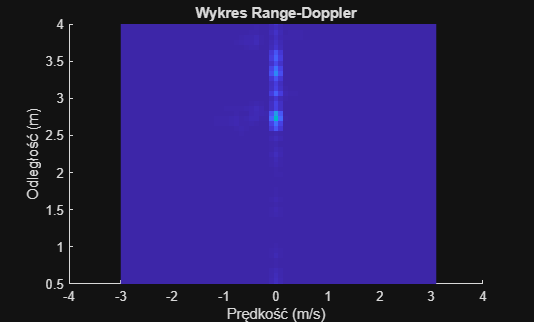

angLimits=iwr.scanAnglesRange;

cube=dr.read(1,1);
cube = iwr.arrangeVirtualDataAngleULA(cube);
mcrDopSize=flip(size(cube)); % dop,rx,range
mcrDopSize(3)=numFrames; % dop,rx,frame
mcrDop=zeros(mcrDopSize);
mcrDopTime=(1:numFrames)*iwr.config.FramePeriodicity*1e-3;
clear mcrDopSize

angGrid=iwr.mvdrEstimator.ScanAngles;

bg = zeros(size(cube));

for i=1:numFrames
    srcCube = dr.read(1,i);
    srcCube = iwr.arrangeVirtualDataAngleULA(srcCube);

    [resp,rngGrid,dopGrid] = iwr.rdResponse(srcCube);
    [rngIdxs, rngGrid]= getLimitedIndexRangesFromDataRanges(rngGrid, rangeLimits);
    resp = abs(resp(rngIdxs,:,:));
    mcrDop(:,:,i)=squeeze(sum(resp,1))';
    figure(1);
    hold on;
    imagesc(dopGrid,rngGrid,squeeze(resp(:,1,:)));
    hold off;
    set(gca, 'YDir','normal');
    xlabel('Prędkość (m/s)');
    ylabel('Odległość (m)');
    title('Wykres Range-Doppler');
    ylim(rangeLimits);
    saveToGif(data_src,"RD");
end

figure;
avg=10; % frames
bgSpeedLimit=0.1; % m/s
winLen=25; % frames

maxFr=numFrames-winLen;
out = abs(squeeze(mcrDop(:,4,:)));

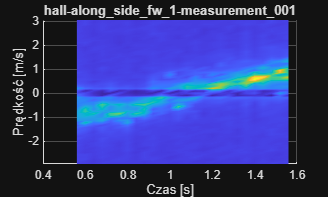

fr = 14;

% showMicroDoppler(mcrDopTime(fr:fr+winLen),dopGrid,out(:,fr:fr+winLen),dataName);
showMicroDoppler(mcrDopTime(fr:fr+winLen),dopGrid,removeMicroDopplerBg(out(:,fr:fr+winLen),bgSpeedLimit,dopGrid,avg),dataName);

function data=removeMicroDopplerBg(mcrDop,bgLimit, dopGrid, movMeanLen)
    data = mcrDop; %dop,frames
    [idxs,~]=getLimitedIndexRangesFromDataRanges(dopGrid,[-bgLimit bgLimit]);
    data(idxs,:) = abs(data(idxs,:) - movmean(data(idxs,:),movMeanLen,2));
end

function showMicroDoppler(mcrDopGrid,dopGrid,data,plotTitle)
    surf(mcrDopGrid,dopGrid,data);
    shading interp;
    title(plotTitle, 'Interpreter', 'none')
    xlabel("Czas [s]")
    ylabel("Prędkość [m/s]")
    ylim(sort(dopGrid([1 end])))
    % view([0 4])
    view([0 90])
end
function [indexArr,croppedRange]=getLimitedIndexRangesFromDataRanges(srcRange,limits)
    if iscolumn(limits)
        limits = limits';
    end
    if xor(isrow(srcRange),isrow(limits))
        [~,startStop] = min(abs(srcRange-limits));
    else
        [~,startStop] = min(abs(srcRange'-limits));
    end
    startStop=sort(startStop);
    indexArr=startStop(1):startStop(2);
    croppedRange = srcRange(indexArr);
end
function saveToGif(data_src,name)
exportgraphics(gcf,data_src+'\'+name+'.gif','Append',true);
end